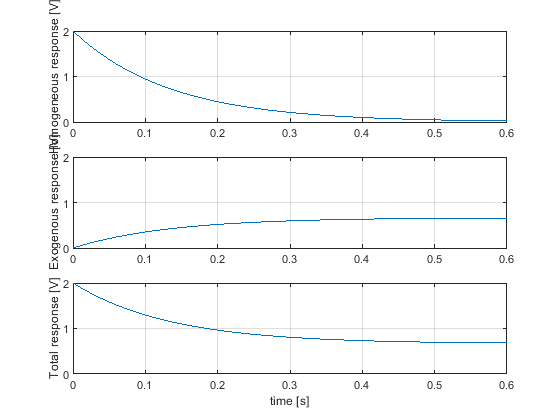

% Matlab Simulation: RC Circuit

% Circuit Parameters
R1 = 1000; % ohms
R2 = 2000; % ohms
C = 200e-6; % Farads

% Calculate circuit constants
a = (R1 + R2) / (R1 * R2 * C);
b = 1 / (R1 * C);

% Initial condition
v0 = 2; % Initial voltage

% Simulation duration
dur = 0.6; % seconds

% Time vector
t = 0:0.01:dur;

% Homogeneous Response
yH = v0 * exp(-a * t);

% Exogenous Response
yE = (b / a) * (1 - exp(-a * t));

% Total Response
yT = yH + yE;

% Plotting
subplot(311); 
plot(t, yH); 
axis([0 dur 0 2]); 
ylabel('Homogeneous response [V]'); 
grid on;

subplot(312); 
plot(t, yE); 
axis([0 dur 0 2]); 
ylabel('Exogenous response [V]'); 
grid on;

subplot(313); 
plot(t, yT); 
axis([0 dur 0 2]); 
ylabel('Total response [V]'); 
xlabel('time [s]'); 
grid on;